# Розрахунково-Графічна робота

## студента: Красницького Микити.     Варіант - 6 

# Завдання 2

Зобразити часові діаграми сигналів передачі даних : дані, що передаються - шифр кафедри (ТОР – це шифр РС, РТПС – це шифр РТ, РОС - це шифр РА ) та номер варіанту N. Дані являються символами ASCII. через інтерфейс:

Inter-integrated Circuit (I2C). 

Номер варіанту – це адресний кадр.

Початкові умови:

clear all
close all
Variant    = 6;
AdrFrame   = Variant;
Code       = unicode2native('РТПС', 'koi-8');
SampleStep = 40;

MATLAB підтримує кодування кирилиці в koi-8 і не підтримує в ASKII

# Передача 7ми розрядної адреси 

## Формую сигнал SDA

Для цього створюю массив данних, що має містити SDA (7-ми розрядна адреса)

dataArray(7) = 0;
for i = 1:7
    if (AdrFrame >= power(2, 7-i))
        dataArray(i) = 1;
        AdrFrame = AdrFrame - power(2, 7-i);
    else
        dataArray(i) = 0;
    end
end
disp(dataArray)

     0     0     0     0     1     1     0



Починаю SDA з високого рівня що спадає

(Перший цикл описує який блок/біт змінюється, другий цикл заповнює цей блок семплами, щоб розтягнути сигнал у часі)

SDA_adr(15*SampleStep) = 0;
for i = 1:2
    for j = 1:SampleStep
        SDA_adr( (i-1)*SampleStep + j ) = 2 - i;
    end
end

Додаю 7 біт інформаційних даних. Дані починаються з самого старшого біта, отже індексація інвертується

for i = 3:9
    for j = 1:SampleStep
        SDA_adr( (i-1)*SampleStep + j ) = dataArray(i - 2);
    end
end

Після чого вказую, що я хочу передати дані - Write (біт 0)

WriteMode = 0;
ReadMode  = 1;
for j = 1:SampleStep
    SDA_adr(9*SampleStep + j) = WriteMode;
end

Приймальний пристрій має подати знак, що дані отримані опустивши SDA до нуля після прийняття 8ми біт. AKG bit запишу просто як нуль

AkgBit = 0;
for j = 1:SampleStep
    SDA_adr(10*SampleStep + j) = AkgBit;
end

Після цього SDA встановлюэться в 1, а SCL зупиняється. Master готовий видавати дані. Режим очікування перед подачею наступних пакетів зображу декількома (4) бітами затримки

IdleBit = 1;
for i = 11:14
    for j = 1:SampleStep
        SDA_adr(i*SampleStep + j) = IdleBit;
    end
end

## Формую SCL сигнал для передачі адреси

Починаэться все з того, що SDA на 2ому біті виконує Start-bit. Отже в цей час SCL має бути високим, а потім впасти до нуля. Довжини імпульсів SCL будуть більш короткими.

SclStep = SampleStep/2; 
SCL_adr(30*SclStep) = 0;
for i = 1:3
    for j = 1:SclStep
        SCL_adr( (i-1)*SclStep + j ) = 1;
    end
end
for j = 1:SclStep
    SCL_adr( 3*SclStep + j ) = 0;
end

SCL має бути у високому стані посередині біту SDA, а інший час він має бути в нулі. Отже якщо знову прийняти перший цикл за нумерацію біта

HighStep = SampleStep/4;
LowStep  = 3*SampleStep/4;
OffSet   = 3*SampleStep/8;

for i = 1:OffSet
    SCL_adr( 2*SampleStep + i) = 0;
end

for i = 2:10
    for j = 1:HighStep
        SCL_adr( i*SampleStep + j + OffSet) = 1;
    end
    for j = HighStep:(LowStep+HighStep)
        SCL_adr( i*SampleStep + j + OffSet) = 0;
    end
end

## Виводжу SDA та SCL для передачі адреси. 

Рівень SCL зменьшив на 10% щоб краще оцінити логічні стани в кожен момент часу.

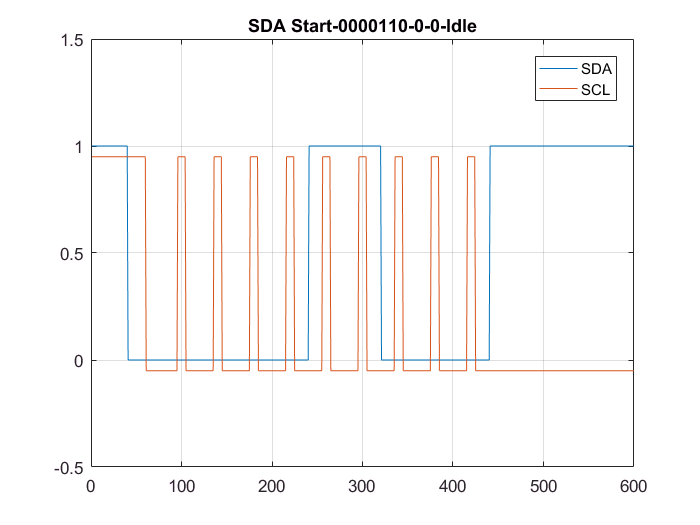

Time = SampleStep * 15;
t = linspace (1, Time, Time);

plot( t, SDA_adr);
hold on
axis([0 Time -0.5 1.5]);
title('SDA Start-0000110-0-0-Idle');
grid on;
plot( t, SCL_adr - 0.05);
legend('SDA', 'SCL');
hold off

# Передача слова

## Формую SDA для ряду пакетів, що перенесуть повідомлення "РТПС"

Створюю масив данних

DataArr = 0;
DataArr(4, 8) = 0;
Code_t = Code;
for i = 1:4
   for j = 1:8
       if (Code_t(i) >= power(2, 8-j))
           %disp([num2str(Code_t(i)),' - ', num2str(power(2, 8-j))])
            DataArr(i, j) = 1;
            Code_t(i) = Code_t(i) - power(2, 8-j);
        else
            DataArr(i, j) = 0;
        end

   end
end

Розтягую дані масива у часі. Передаватимуться 4 літери. Кожна літера має 8 байт інформації, 1 байт підтвердження та, нехай, 1 байт затримки.

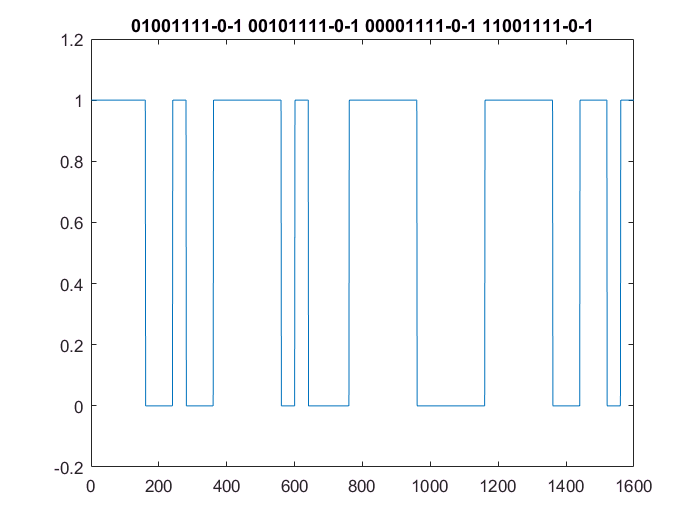

SDA_words = 0;
SDA_words(4*10*SampleStep) = 0;
for z = 1:4
    z_index = (z-1)*10*SampleStep;
    % Data Block
    for i = 1:8
       for j = 1:SampleStep 
           SDA_words( z_index + (i-1)*SampleStep + j ) = DataArr (z, i);
       end
    end
    % AKG Block
    for j = 1:SampleStep 
       SDA_words( z_index + 8*SampleStep + j ) = 0;
   end
    %Idle Block
    for j = 1:SampleStep 
       SDA_words( z_index + 9*SampleStep + j ) = 1;
   end
end

t_word = linspace(1, 1600, 1600);
plot(t_word, SDA_words);
title('01001111-0-1 00101111-0-1 00001111-0-1 11001111-0-1');
axis([0 1600 -0.2 1.2]);

## Формую SCL для ряду пакетів, що перенесуть повідомлення "РТПС"

SCL_words = 0;
SCL_words(4*10*SampleStep) = 0;
HighStep = SampleStep/4;
LowStep  = 3*SampleStep/4;
OffSet   = 3*SampleStep/8 ;

for i = 1:OffSet
    SCL_words(i) = 0;
end

for z = 1:4
    z_index = (z-1)*10*SampleStep;
    for i = 2:10
        for j = 1:HighStep
            SCL_words( z_index + (i-2)*SampleStep + j + OffSet) = 1;
        end
        for j = HighStep:(LowStep+HighStep)
            SCL_words( z_index + (i-2)*SampleStep + j + OffSet) = 0;
        end
    end
end

## Виводжу SDA та SCL для передачі слова. 

Рівень SCL зменьшив на 10% щоб краще оцінити логічні стани в кожен момент часу.

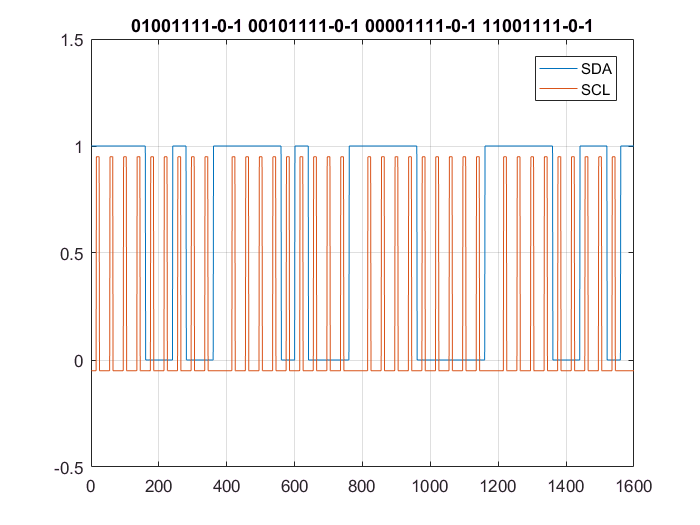

Time = SampleStep * 4*10;
t = linspace (1, Time, Time);

plot( t, SDA_words);
hold on
axis([0 Time -0.5 1.5]);
title('11110010-0-1 11110100-0-1 11110000-0-1 11110011-0-1');
grid on;
plot( t, SCL_words(1:1600) - 0.05);
legend('SDA', 'SCL');
hold off

## Stop Bit

Стан зупинки визначається переходом 0 -> 1 (низький в високий) на SDA після переходу 0 -> 1 на SCL, причому SCL залишається високим.

SDA_stop = 0;
SDA_stop(2*SampleStep) = 0;
SDA_stop(1:SampleStep) = 0;
SDA_stop(SampleStep:2*SampleStep) = 1;

SCL_stop = 0;
SCL_stop(2*SampleStep) = 0;
SCL_stop(1:SampleStep/2) = 0;
SCL_stop(SampleStep/2:2*SampleStep) = 1;

Time = SampleStep * 2
t = linspace (1, Time, Time);

plot(t, SDA_stop);
hold on
axis([0 Time -0.5 1.5]);
title('Stop bit');
grid on;
plot(t, SCL_stop - 0.05);
legend('SDA', 'SCL');
hold off

# Епюри SDA та SCL

%SDA(1:15*SampleStep)             = SDA_adr(1:15*SampleStep);
%SDA(15*SampleStep:55*SampleStep) = SDA_words(1:40*SampleStep);
%SDA(55*SampleStep:57*SampleStep) = SDA_stop(1:2*SampleStep);

%SCL(1:15*SampleStep)             = SCL_adr(1:15*SampleStep);
%SCL(15*SampleStep:54*SampleStep) = SCL_words(1:40*SampleStep);
%SCL(54*SampleStep:55*SampleStep) = SCL_stop(1:2*SampleStep);
SDA(55*SampleStep) = 0;
SCL(55*SampleStep) = 0;
for i = 1:15*SampleStep
    SDA(i) = SDA_adr(i);
    SCL(i) = SCL_adr(i);
end
for i = (15*SampleStep + 1):55*SampleStep
    SDA(i) = SDA_words(i - 15*SampleStep);
    SCL(i) = SCL_words(i - 15*SampleStep);
end
for i = (55*SampleStep + 1):57*SampleStep
    SDA(i) = SDA_stop(i - 55*SampleStep);
    SCL(i) = SCL_stop(i - 55*SampleStep);
end

Time = SampleStep * 57;
t = linspace (1, Time, Time);

plot(t, SDA);
hold on
axis([0 Time -0.5 1.5]);
title('SDA SCL. Adress - 6. Message - "РТПС"');
grid on;
plot(t, SCL - 0.05);
legend('SDA', 'SCL');
hold off